# 非线性回归

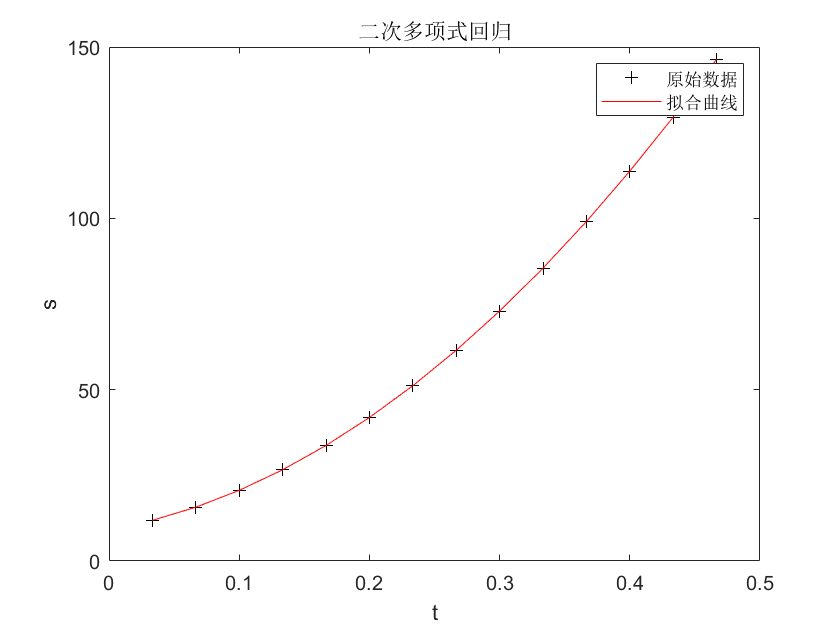

% 例题1
% 二次多项式回归
t = 1/30:1/30:14/30;
s = [11.86 15.67 20.6 26.69 33.71 41.93 51.13 61.49 72.9 85.44 99.08 113.77 129.54 146.48];
[p, S] = polyfit(t, s, 2);  % 进行二次拟合

% 预测及作图
Y = polyconf(p, t, S); % 计算拟合曲线的预测值
plot(t, s, 'k+', t, Y, 'r');    % 绘制原始数据点和拟合曲线
xlabel('t');
ylabel('s');
title('二次多项式回归');
legend('原始数据','拟合曲线');

% 化为多元线性回归
t = 1/30:1/30:14/30;
s = [11.86 15.67 20.6 26.69 33.71 41.93 51.13 61.49 72.9 85.44 99.08 113.77 129.54 146.48];
T = [ones(14, 1), t', (t.^2)']; % 构建多元线性回归的自变量矩阵
[b, bint, r, rint, stats] = regress(s', T); % 进行多元线性回归分析
b

b =     9.1329
   65.8896
  489.2946


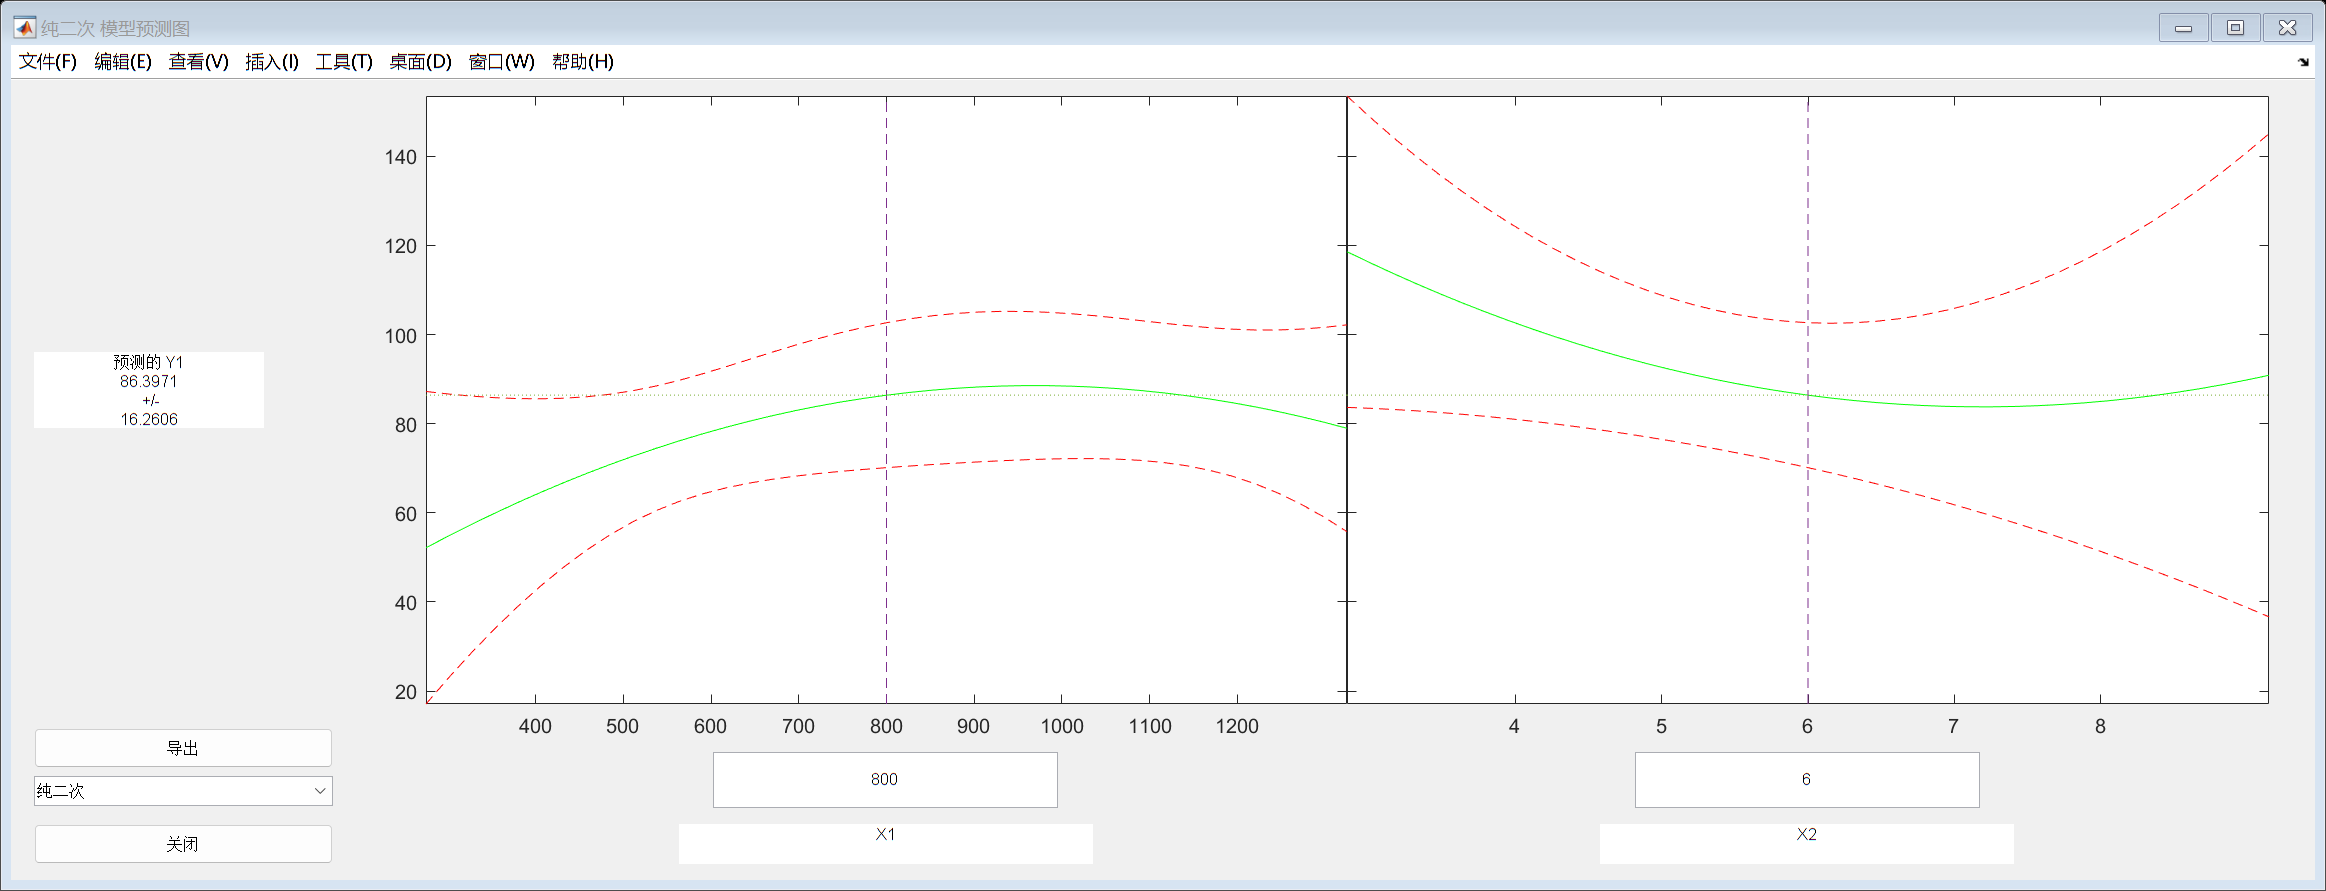

% 例题2
% 直接用多元二项式回归
x1 = [1000 600 1200 500 300 400 1300 1100 1300 300];
x2 = [5 7 6 6 8 7 5 4 3 9];
y  = [100 75 80 70 50 65 90 100 110 60]';
x  = [x1' x2'];
rstool(x, y, 'purequadratic')   % 使用多元二项式回归工具箱进行回归分析

beta, rmse  % 回归系数和剩余标准差

beta =    11.6037
   -1.0641


函数或变量 'rmse' 无法识别。

X = [ones(10, 1) x1' x2' (x1.^2)' (x2.^2)'];    % 多元线性回归的自变量矩阵
[b, bint, r, rint, stats] = regress(y, X);  % 进行多元线性回归分析
% b, stats
% 例题3
clear;clc;
x = 2:16;
y = [6.42 8.20 9.58 9.5 9.7 10 9.93 9.99 10.49 10.59 10.60 10.80 10.60 10.90 10.76];
beta0 = [8 2]';

% 求回归系数
[beta, r, J] = nlinfit(x', y', 'volum', beta0);
beta  % 回归系数
% 预测及作图
[YY, delta] = nlpredci('volum', x', beta, r, J); % 预测因变量的值及置信区间
plot(x, y, 'k+', x, YY, 'r')    % 绘制原始数据点和拟合曲线